# PacWave Resource Assessment

This provides an example using MHKiT to perform a resource assessment similar to Dunkel et. al at the PACWAVE site following the IEC 62600-101 where applicable. PacWave is an open ocean, grid-connected, full-scale test facility consisting of two sites (PacWave-North & PacWave-South) for wave energy conversion technology testing located just a few miles from the deep-water port of Newport, Oregon. This example notebook performs a resource analysis using omni-directional wave data from a nearby NDBC buoy and replicates plots created by Dunkel et. al and prescribed by IEC TS 62600-101 using these data.

Dunkle, Gabrielle, et al. "PacWave Wave Resource Assessment." (2020).

## Buoy Location

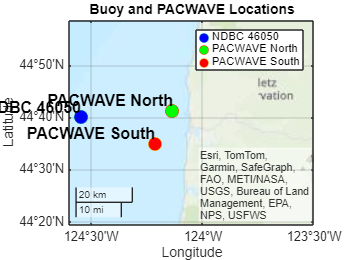


% Define the map center and zoom level
lat_center = 44.613600975457715;
lon_center = -123.74317583354498;

% Create a figure with geographic axes
figure;
geoax = geoaxes; % Create geoaxes for mapping
hold(geoax, 'on');
geolimits([44.5, 44.8], [-124.6, -123.5]); % Adjust limits for better visibility
title('Buoy and PACWAVE Locations');

% Define marker locations and labels
locations = [
    44.669, -124.546;   % NDBC 46050
    44.69, -124.1347;   % PACWAVE North
    44.5844, -124.2125  % PACWAVE South
];

labels = {'NDBC 46050', 'PACWAVE North', 'PACWAVE South'};
colors = {'b', 'g', 'r'};

% Plot each location on the map
for i = 1:length(labels)
    geoplot(geoax, locations(i,1), locations(i,2), 'o', 'MarkerSize', 10, ...
        'MarkerFaceColor', colors{i}, 'DisplayName', labels{i});
    text(locations(i,1), locations(i,2), labels{i}, 'VerticalAlignment', 'bottom', ...
        'HorizontalAlignment', 'right', 'FontSize', 12, 'FontWeight', 'bold');
end
geobasemap topographic % satellite

% Add a legend
legend(geoax, 'Location', 'best',location = 'northeast');


%% Retrieve buoy metadata from NOAA NDBC
buoy_number = '46050';
url = "https://www.ndbc.noaa.gov/station_page.php?station=" + buoy_number;

try
    options = weboptions('Timeout', 10);
    data = webread(url, options);
    
    fprintf('Buoy Metadata for %s:\n', buoy_number);
    data % Display the retrieved data
    
catch ME
    warning('Error retrieving data: %s', ME.message);
end

Buoy Metadata for 46050:


<!DOCTYPE html>
<html lang="en">
<head>



<meta name="viewport" content="width=device-width, initial-scale=1.0">
<link rel="schema.DC" href="http://purl.org/dc/elements/1.1/">
<meta http-equiv="Content-Type" content="text/html; charset=iso-8859-1">
<meta name="DC.title" content="NDBC Station Page">
<meta name="DC.description" content="National Data Buoy Center - Recent observations from buoy 46050 (44.669N 124.546W) - STONEWALL BANK - 20NM West of Newport, OR.">
<meta name="description" content="National Data Buoy Center - Recent observations from buoy 46050 (44.669N 124.546W) - STONEWALL BANK - 20NM West of Newport, OR.">
<meta name="DC.subject" content="weather, buoy, weather buoy, marine, forecast, hurricane, wind, wave, offshore, surfing, temperature, meteorology, climate, ocean">
<meta name="DC.creator" content="US Department of Commerce, National Oceanic and Atmospheric Administration, National Weather Service, National Data Buoy Center">
<meta name="DC.language" content="EN-US"

## Buoy Metadata

The MHKiT function `get_buoy_metadata` will fetch the metadata for a given National Data Buoy Center (NDBC) buoy. In this case the station number nearest to PACWAVE is '46050'. This metadata can provide important background information about the buoy to help users understand the source of the data they are working with and ensure that the buoy's location and characteristics are suitable for their specific analysis. Note that optional buoy keys will be assigned as metadata keys with empty values. This can be seen in the example below for "SCOOP Payload".

% Get buoy metadata
buoy_metadata = get_buoy_metadata(buoy_number)
disp('Buoy Metadata:');
fields = fieldnames(buoy_metadata);
for i = 1:numel(fields)
    key = fields{i};
    value = buoy_metadata.(key);
    fprintf('%s: %s\n', key, value);
end
